# Exercise 14

Wavefront Planner

Author: Manxi Lin Date:03/25/2020

clear; close all; clc;

## Q1

Implement a queue that can hold cell coordinates and a function to insert an element and a function to retrieve an element.

% Create an object queue to hold the coordinates
% matrix in q is read-only
% two methods: push:add a new element in the end of the queue
% pop: take away the first element in the queue
% e.g
q = Queue();
q.push([1;1]);
q.push([4;6]);
q.push([7;8]);
q.push([10;17;99]);

Push Error: Dat Size Error


q.matrix

ans =      1     4     7
     1     6     8


q.pop

ans =      1
     1


q.pop

ans =      4
     6


q.matrix

ans =      7
     8


## Q2

% find neighbour
% 8-connectivity
map = zeros(100,100);
cell = [5;5];
Nb = findNb(map, cell)

Nb =      4     4     4     5     5     6     6     6
     4     5     6     4     6     4     5     6


cell = [1;1];
Nb = findNb(map, cell)

Nb =      1     2     2
     2     1     2


% 4-connectivity
cell = [5;5];
Nb = findNb(map, cell, 4)

Nb =      4     5     5     6
     5     4     6     5


cell = [1;1];
Nb = findNb(map, cell, 4)

Nb =      1     2
     2     1


## Q3

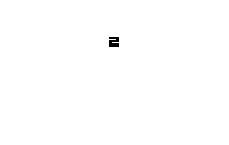

% Let's test our script on waveplannerexample.pdf
map = zeros(10, 10);
map(3, 1:7) = 1;
map(6, 4:10) = 1;
figure;
imshow(map);

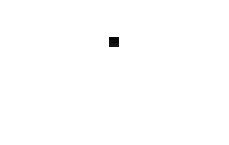

distmap = makeWave(map, [10;9], [1;1]);
figure;
imshow(uint8(distmap));

## Q4

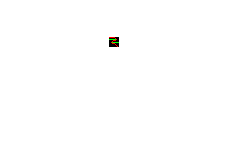

[route, wp] = findRoute(distmap, map, [10;9], [1;1]);
image = zeros(10,10,3);
image(:,:,1) = route;
image(:,:,2) = map;
imshow(image)

## Q5

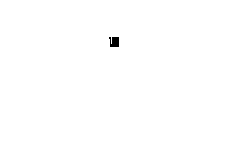

map = zeros(10,10);
map(1:7, 3) = 1;
map(3:10) = 1;
imshow(map);

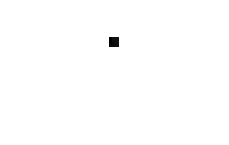

goal = [2;2];
start = [9;9];
distmap = makeWave(map, start, goal);
figure;
imshow(uint8(distmap));

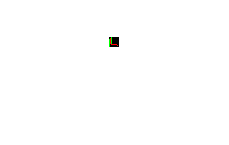

[route, wp] = findRoute(distmap, map, start, goal);
image = zeros(10,10,3);
image(:,:,1) = route;
image(:,:,2) = map;
imshow(image)

## Q7

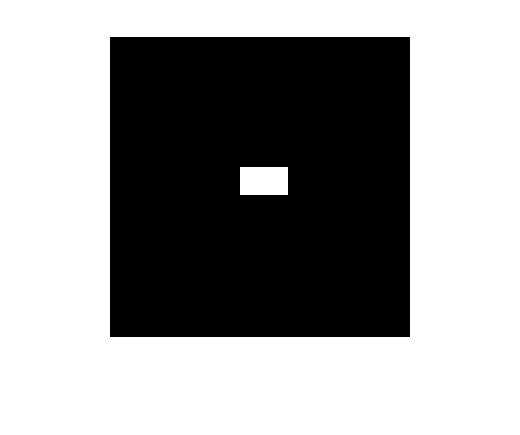

% Let's assume there is a cardboard box
map = zeros(300,300);
map(131:158, 131:178) = 1;
imshow(map);

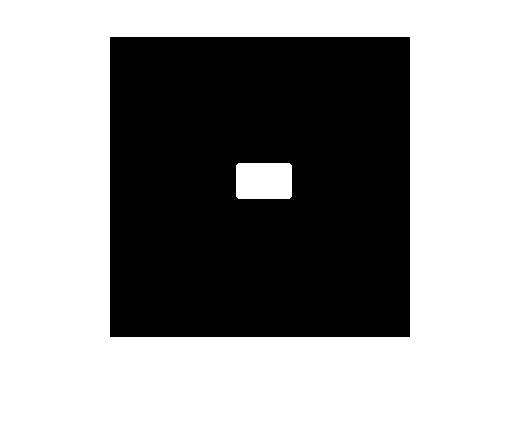

str = strel('disk',5);
map = imdilate(map, str);
imshow(map);

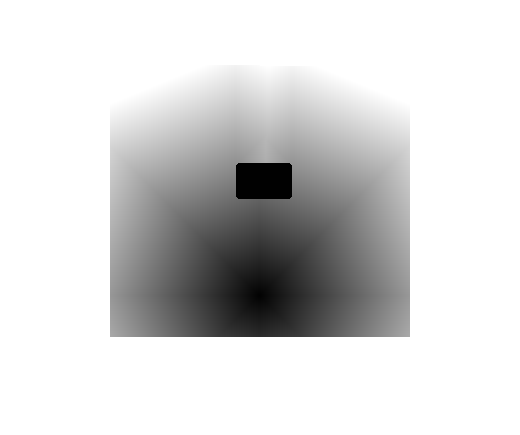

goal = [259;150];
start = [30;150];
distmap = makeWave(map, start, goal);
figure;
imshow(uint8(distmap));

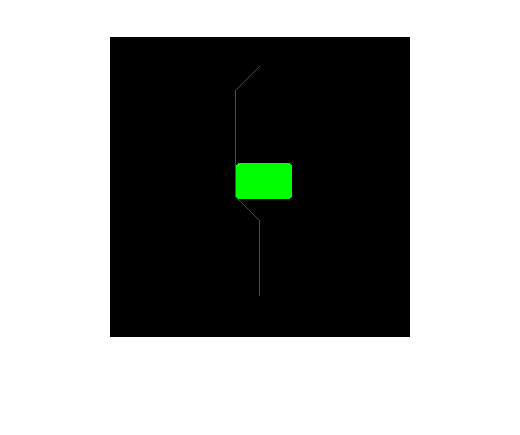

[route, wp] = findRoute(distmap, map, start, goal);
image = zeros(300,300,3);
image(:,:,1) = route;
image(:,:,2) = map;
imshow(image)